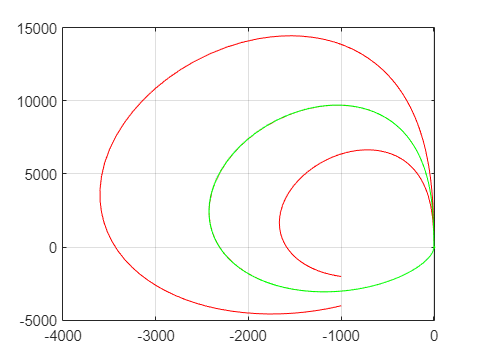

clear all; syms x
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;
%title_coefQs=[ 'a1=', num2str(a1) ,';b1=', num2str(b1) ,';c1=', num2str(c1) ,';\ alpha_1=', num2str(al1), ';\ beta_1=', num2str(bt1) ,';a2=', num2str(a2) ,'; b2=' num2str(b2) ,';c2= ', num2str(c2) ,';\ alpha_2=', num2str(al2), ';\ beta_2=', num2str(bt2)];

RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');

x0=x0_1 ; y0=0;[T, XY]= ode45(@fQsys, [0 len1], [x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;
x0=x0_2 ; y0=0;[T, XY]= ode45(@fQsys, [0 len2], [x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;

x0=x0_2 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len3 ] ,[ x0 y0 ], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
hold on; grid on;
x0=x0_3 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len4 ] ,[ x0 y0 ], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
hold on; grid on;

x0=x0_3 ; y0=0;[T, XY]= ode45(@fQsys ,[0 len5] ,[x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
hold on; grid on;
x0=x0_4 ; y0=0;[T, XY]= ode45(@fQsys ,[0 len6] ,[x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
hold on; grid on;

x0=-1000; y0=y0_1 ;[T, XY]= ode45(@fQsys ,[0 len7] ,[x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
hold on; grid on;
x0=-1000; y0=y0_2 ;[T, XY]= ode45(@fQsys ,[0 len8] ,[x0 y0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');

hold on; grid on;
hold off

% title({title_coefQs})

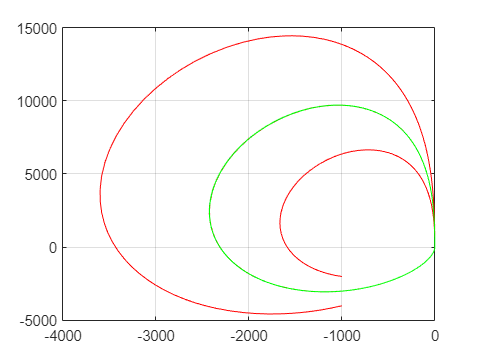

clear all; syms x
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;

RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');

[T, XY]= ode45(@fQsys, [0 len7], [-1000 y0_1], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;
[T, XY]= ode45(@fQsys, [0 len8], [-1000 y0_2], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
grid on;

hold off

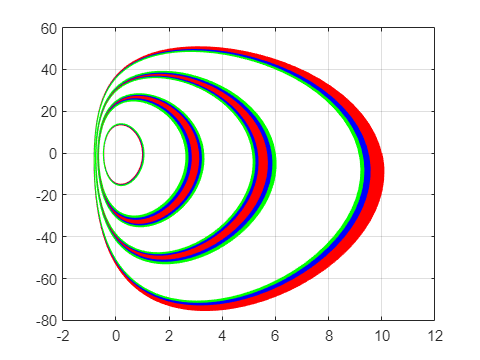


[T, XY]= ode45(@fQsys, [0 len1], [x0_1 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;
[T, XY]= ode45(@fQsys, [0 len2], [x0_2 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;

[T, XY]= ode45(@fQsys, [0 len3], [x0_2 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;
[T, XY]= ode45(@fQsys, [0 len4], [x0_3 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;

[T, XY]= ode45(@fQsys, [0 len5], [x0_3 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
hold on; grid on;
[T, XY]= ode45(@fQsys, [0 len6], [x0_4 0], options);
fPlotTrajectory(XY(: ,1), XY(: ,2), 'red','blue','green');
grid on;

hold off

% clear all; syms x
% global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
% 
% a1=1;b1=1;c1=0;al1=0;bt1=1;
% a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
% x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
% acc=10^(-5); y0_1=-2000; y0_2=-4000; 
% len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;
% 
% f=fcyclesPlot(a1, b1, c1, al1, bt1, a2, b2, c2, al2, bt2, x0_1, x0_2, x0_3, x0_4, y0_1, y0_2, acc, len1, len2, len3, len4, len5, len6, len7, len8)
% function f=fcyclesPlot(a1, b1, c1, al1, bt1, a2, b2, c2, al2, bt2, x0_1, x0_2, x0_3, x0_4, y0_1, y0_2, acc, len1, len2, len3, len4, len5, len6, len7, len8)
% 
% title_coefQs=[ 'a1=', num2str(a1) ,';b1=', num2str(b1) ,';c1=', num2str(c1) ,';\ alpha_1=', num2str(al1), ';\ beta_1=', num2str(bt1) ,';a2=', num2str(a2) ,'; b2=' num2str(b2) ,';c2= ', num2str(c2) ,';\ alpha_2=', num2str(al2), ';\ beta_2=', num2str(bt2)];
% RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
% options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');
% 
% x0=x0_1 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len1 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% x0=x0_2 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len2 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% 
% x0=x0_2 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len3 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% x0=x0_3 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len4 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% 
% x0=x0_3 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len5 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% x0=x0_4 ; y0=0;[ T, XY ]= ode45(@fQsys ,[0 len6 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% 
% x0=-1000; y0=y0_1 ;[ T, XY ]= ode45(@fQsys ,[0 len7 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% x0=-1000; y0=y0_2 ;[ T, XY ]= ode45(@fQsys ,[0 len8 ] ,[ x0 y0 ], options);
% fPlotTrajectory(XY(: ,1), XY(: ,2), 'red ','blue ','green ');
% hold on; grid on;
% hold off
% title({title_coefQs})
% 
% end

Additional functions

function f=fPlotTrajectory(X ,Y, Color1, Color2, Color3)

lenTr=length(X); lenTr3=round(lenTr /9);
lenColor1=round(4* lenTr3); lenColor2=round(7* lenTr3);

plot(X(1 : lenColor1), Y(1 : lenColor1), Color1); hold on;
plot(X(lenColor1 : lenColor2), Y(lenColor1 : lenColor2), Color2);
hold on;
plot(X(lenColor2 : length(X)), Y(lenColor2 : length(Y)), Color3);
end
function dz=fQsys(t, z) %
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)

dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

